# TP 2

# Partie 1 : Covolution 

## Question 1

### Pour se familiariser avec le produit de convolution, reproduire les expériences de la page  35 et 36 de votre poly. Pour cela :

Créer une image noire dont le cercle de rayon R=20 pixels est blancs :

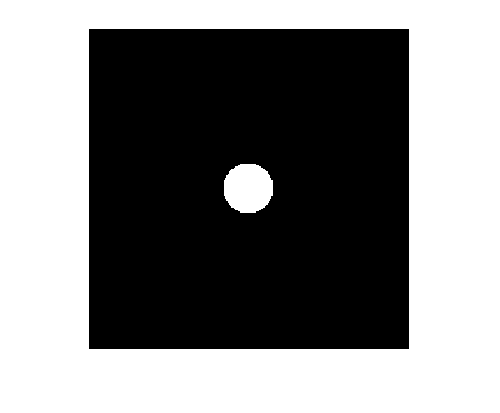

%Création de l'image noire 256x256 stockée dans Itest, utiliser la fonction zeros()
n=256;
R=20;
Itest=zeros(n);
D=Itest;
% Mise en blanc des pixels centraux 
xc=n/2;
yc=n/2;
for i=1:n
    for j=1:n
        distx=abs(xc-i);
        disty=abs(yc-j);
        D(i,j)=sqrt(distx*distx+disty*disty);
    end
end
Itest(D<R)=1;
Itest(D>R)=0;
% Affichage de l'image, utiliser la fonction imshow()
imshow(Itest)

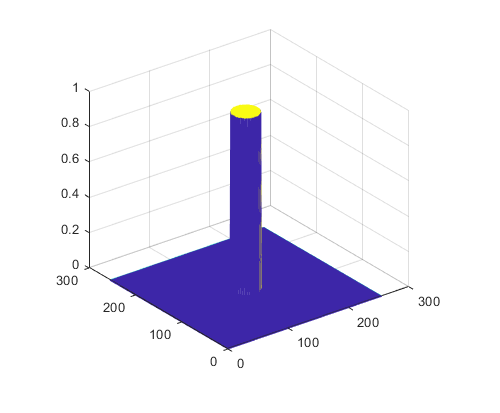

%Affichage de l'image en 3D avec meshz()
meshz(Itest)

Créer la PSF de taille 65x65 :

Aide : En introduisant D(i,j) la distance radiale du pixel (i,j) au centre de l'image, utiliser l'expression : "PSF(i,j)=airy(0.1*D(i,j));"

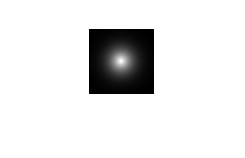

% Création image noire
n=65;
PSF=zeros(n);
xc=n/2;
yc=n/2;
% Double boucle pour créer le motif de la tache d'Airy
for i=1:n
    for j=1:n
        distx=abs(xc-i);
        disty=abs(yc-j);
        D(i,j)=sqrt(distx*distx+disty*disty);
        PSF(i,j)=airy(0.1*D(i,j));
    end
end

% Normalisation de la PSF à 1
PSF=PSF/max(PSF(:));
% Affichage de la PSF avec imshow()
figure,imshow(PSF)

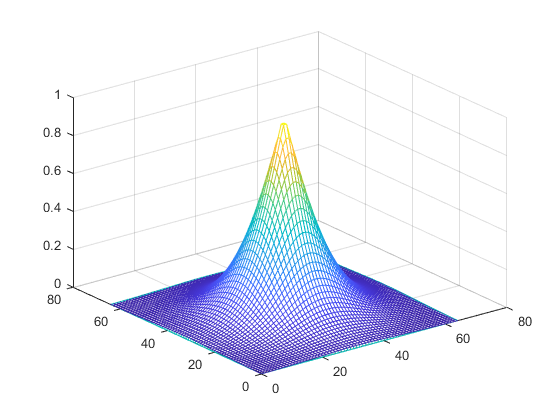

% Affichage de la PSF avec meshz()
figure,meshz(PSF) 

Faire la convolution de l'image du rond blanc avec la PSF normalisée:

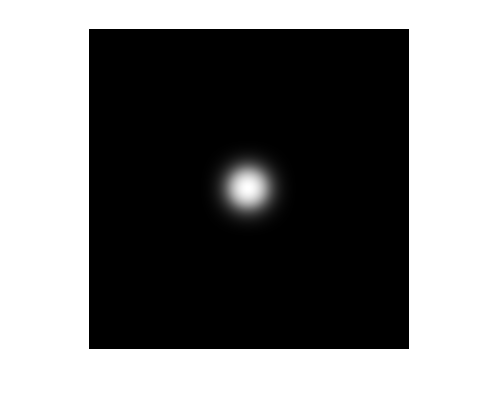

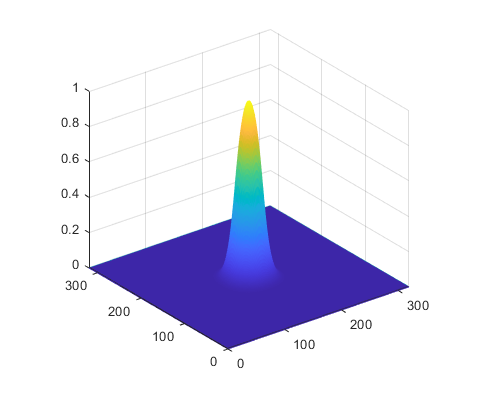

% Créer l'image convoluée avec conv2()
Convol = conv2(Itest,PSF);
% Normalisation de l'image convoluée
Convol=Convol/max(Convol(:));
% Afficher la convolution avec imshow()
imshow(Convol)
% Affichage de la PSF avec meshz()
meshz(Convol)

Commenter l'image obtenue

## Question 2

### Appliquer la même convolution à l'image de Lena.  Pour cela :

Stocker l'image de Lena dans I et la convertir en nuances de gris.

I=rgb2gray(imread("Lena.jpg"));

Appliquer la convolution avec PSF

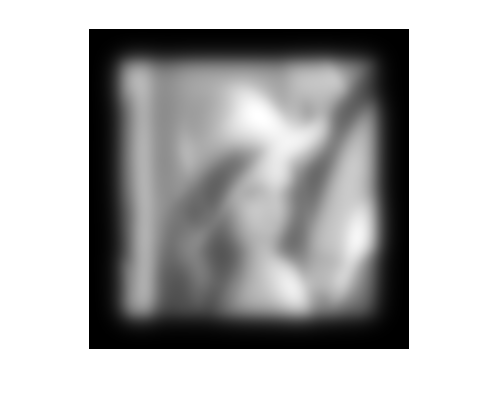

% Créer l'image convoluée avec conv2()
Convol = conv2(I,PSF);
% Normalisation de l'image convoluée
Convol=Convol/max(Convol(:));
% Afficher la convolution avec imshow()
imshow(Convol)

Commenter l'image obtenue, en particulier sa taille, les effets de bords et le rendu de l'image obtenue.

## Question 3 

### Dans l'exemple précédent, la largeur de la PSF était excessivement grande, et la fenetre dans laquelle elle était inscrite également. Réitérer la convolution avec une PSF plus réelle Pour cela :

Créer une PSF de taille 9x9

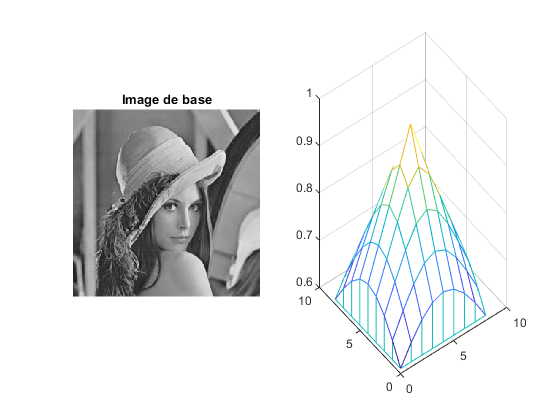

% Création image noire
n=9;
PSF=zeros(n);
xc=round(n/2);
yc=round(n/2);
% Double boucle pour créer le motif de la tache d'Airy
for i=1:9
    for j=1:9
        distx=abs(xc-i);
        disty=abs(yc-j);
        D(i,j)=sqrt(distx*distx+disty*disty);
        PSF(i,j)=airy(0.1*D(i,j));
    end
end

% Normalisation de la PSF à 1
PSF=PSF/max(PSF(:));
% Affichage de la PSF avec imshox()
imshow(PSF)
% Affichage de la PSF avec meshz()
meshz(PSF)

Appliquer la convolution avec PSF

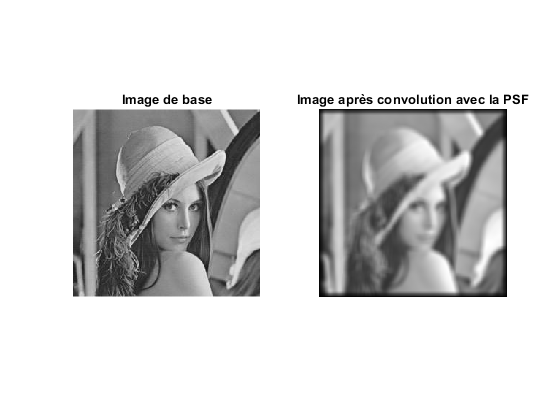

% Créer l'image convoluée avec conv2()
Convol = conv2(I,PSF);
% Normalisation de l'image convoluée
Convol=Convol/max(Convol(:));
% Afficher la convolution avec imshow(), à coté de l'image de base en noir
% et blanc à l'aide de subplot
figure;
subplot(1,2,1)
imshow(I)
title('Image de base')
subplot(1,2,2)
imshow(Convol)
title('Image après convolution avec la PSF')

Commenter l'image obtenue

## Question 4

### La fonction conv2 possède différents arguments "full", "valid" et "same". A quoi correspondent-ils? Pour cela :

Effectuer les convolutions de Lena avec la précédente PSF (9x9), pour chacun des 3 paramètres. Puis afficher les résultats sur une même figure à l'aide de subplot

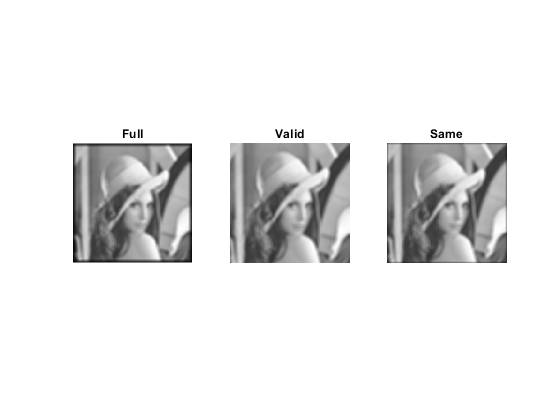

% Stockage et normalisation de la conv avec l'argument 'full'
convFull=conv2(I,PSF,'full');
convFull=convFull/max(convFull(:));
% Stockage et normalisation de la conv avec l'argument 'valid'
convValid=conv2(I,PSF,'valid');
convValid=convValid/max(convValid(:));
% Stockage et normalisation de la conv avec l'argument 'same'
convSame=conv2(I,PSF,'same');
convSame=convSame/max(convSame(:));
% Affichage des résultats à l'aide de imshow() et subplot
figure;
subplot(1,3,1)
imshow(convFull)
title('Full')
subplot(1,3,2)
imshow(convValid)
title('Valid')
subplot(1,3,3)
imshow(convSame)
title('Same')

Commentez les 3 images et conclure quant aux rôles des 3 arguments de la fonction conv2.

'full' — Return the full 2-D convolution.

'same' — Return the central part of the convolution, which is the same size as A.

'valid' — Return only parts of the convolution that are computed without zero-padded edges.

# Partie 2 

# Corrélation 

## Question 5

### Commencer par se familiariser avec la corrélation. Pour cela :

Regarder l'aide Matlab de corr2, puis calculer la corrélation entre I et I, Itest et Itest puis entre I et Itest:

% corrélation entre I et I
corr2(I,I)

ans = 1

% corrélation entre Itest et Itest
corr2(Itest,Itest)

ans = 1

% corrélation entre I et Itest
corr2(I,Itest)

ans = 0.0344

Comment évolue le coefficient de corrélation en fonction de la similarité de deux images ? 

Créer une image similaire à Itest (question1) mais dont le cercle est centré sur le pixel (200,50), stocker la dans ItestDecalee :

% Création de iTestDecalee
n=256

n = 256

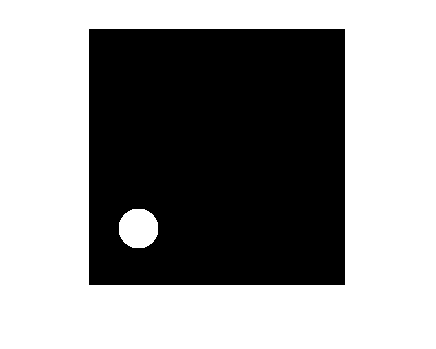

ItestDecalee=zeros(n);
xc=200;
yc=50;
% Mise en blanc des pixels centraux 
for i=1:n
    for j=1:n
        distx=abs(xc-i);
        
        disty=abs(yc-j);
        D(i,j)=sqrt(distx*distx+disty*disty);
    end
end
ItestDecalee(D<R)=1;
ItestDecalee(D>R)=0;
% Affichage de l'image, utiliser la fonction imshow()
figure;
imshow(ItestDecalee)

%Affichage de l'image en 3D avec meshz()
figure;
meshz(ItestDecalee)


Lire l'aide de xcorr2, puis afficher les corrélation croisée de Itest et Itest, puis ItestDecale et ItestDecale et enfin Itest et ItestDecalee :

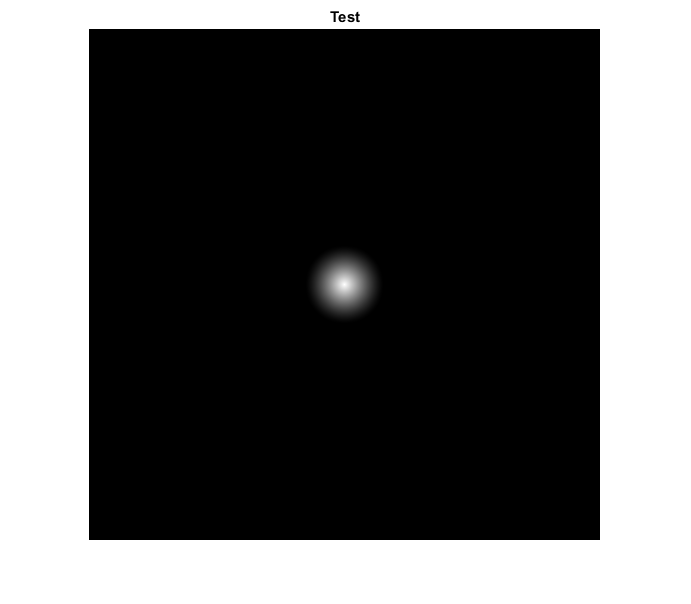

% Calcul de la corrélation croisée de Itest et Itest à l'aide de xcorr(2),
ItestCorr=xcorr2(Itest,Itest);
% Calcul de la corrélation croisée de ItestDecalee et ItestDecale à l'aide de xcorr(2)
IDecaleeCorr=xcorr2(ItestDecalee,ItestDecalee);
% Calcul de la corrélation croisée de Itest et ItestDecale à l'aide de xcorr(2)
ICroiseCorr=xcorr2(Itest,ItestDecalee);

%Normalisation des 3 matrices
ItestCorr=ItestCorr/max(ItestCorr(:));
IDecaleeCorr=IDecaleeCorr/max(IDecaleeCorr(:));
ICroiseCorr=ICroiseCorr/max(ICroiseCorr(:));

% Affichage des résultats avec imshow()
figure;
imshow(ItestCorr)
title('Test')

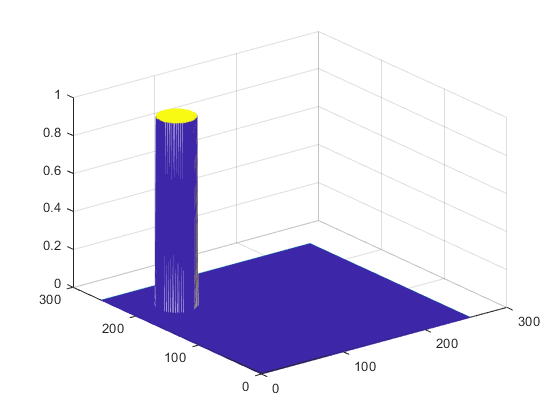

figure;
imshow(IDecaleeCorr)

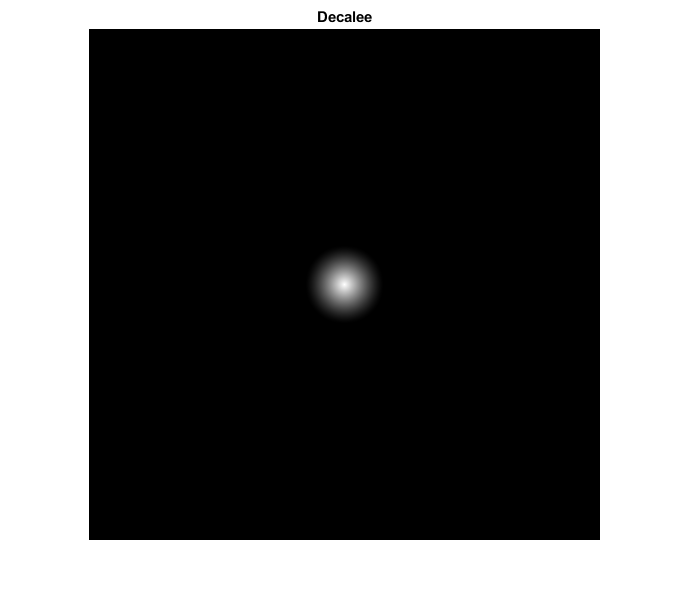

title('Decalee')

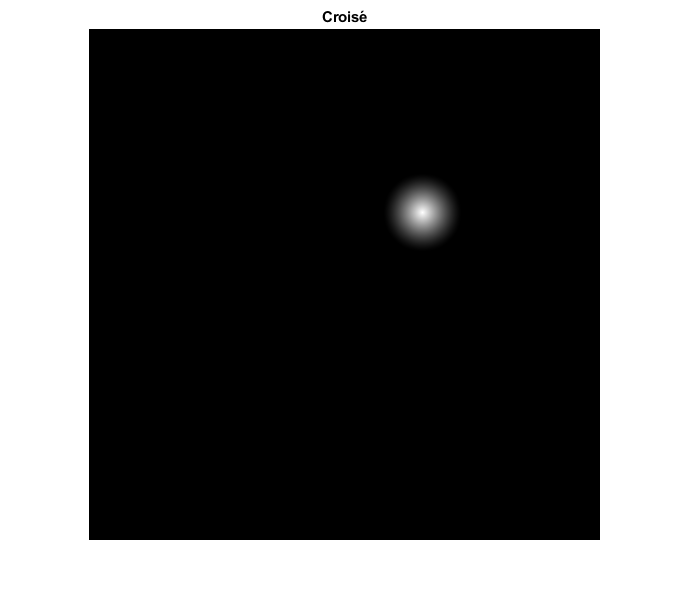

figure;
imshow(ICroiseCorr)
title('Croisé')

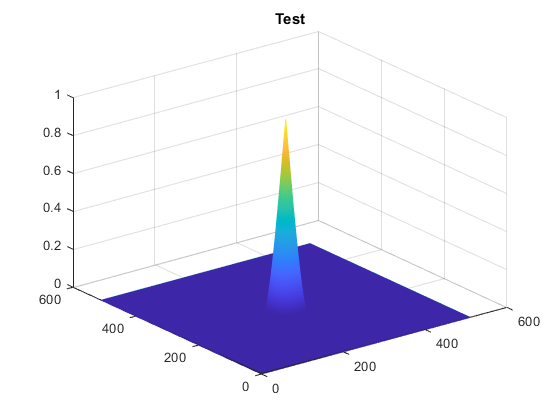

% Affichage des resultats avec meshz()
figure;
meshz(ItestCorr)
title('Test')

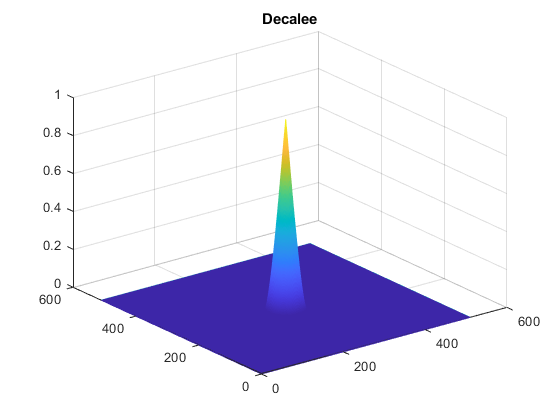

figure;
meshz(IDecaleeCorr)
title('Decalee')

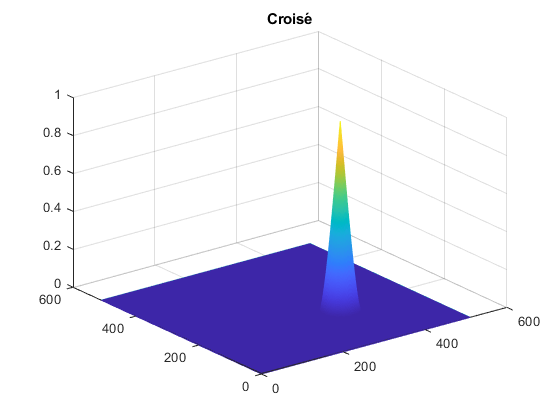

figure;
meshz(ICroiseCorr)
title('Croisé')

A l'aide de la fonction find() relever la position du maximum de la matrice ICroiseCorr

disp(size(ICroiseCorr))

   511   511



% taille après "full" 256+256-1=511,
% donc il ne faut ne prendre que l'image au centre
n0=round(511/4); % index pour le premier pixel de l'image au centre 
ICroiseCorr=ICroiseCorr(n0+1:end-n0,n0+1:end-n0); 
% end = 511 (index pour le dernier pixel)

[li,col]=find(ICroiseCorr==1)

li = 56

col = 206

Calculer la distance de cette position au centre de l'image 

distLi=abs(n/2-li)

distLi = 72

distCol=abs(n/2-col)

distCol = 78

## Les comparer au décalages introduits entre Itest et ItestDecale puis conclure quand à la corrélation croisée entre 2 images

## center original(128,128), center décalé(200,50) 

## => distance x = abs(128-200)=72;

##       distance y= abs(128-50)=78 ;

Regarder la taille de ICroiseCorr, faire l'analogie avec la convolution vue dans la partie 1.

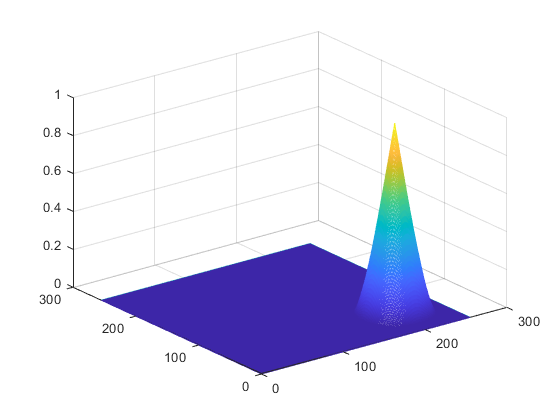

% En fait xcorr(A,B) = conv2(A,rot90(B,2))
% La différence est juste une rotation de 180 dégres

ICroiseCorr=conv2(Itest,rot90(ItestDecalee,2),'same');
% 'same' pour avoir la même taille 
% normalisation 
ICroiseCorr=ICroiseCorr/max(ICroiseCorr(:));
figure,meshz(ICroiseCorr)

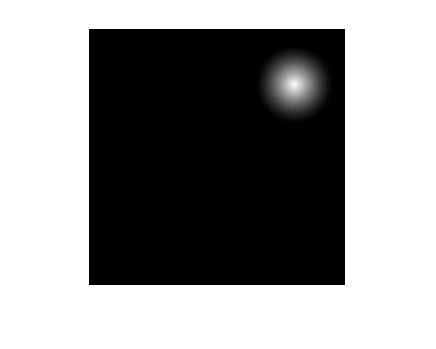

figure, imshow(ICroiseCorr)

[li,col]=find(ICroiseCorr==1)

li = 56

col = 206

## Question 6

### Repérer la position des croix grace à la corrélation croisée de l'image . Pour cela :

Ouvrir pour comprendre la fonction "MettreCroix" puis positionner 5 croix arbitrairement sur une nouvelle image ICroix (256 x 256) 

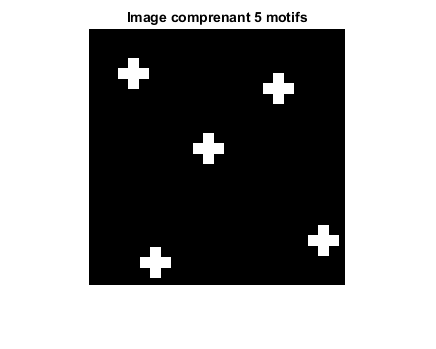

% Ajouts successifs de croix sur l'image ICroix de taile 256x256
ICroix=MettreCroix(zeros(256), 120,120);
ICroix=MettreCroix(ICroix, 60,190);
ICroix=MettreCroix(ICroix, 45,45);
ICroix=MettreCroix(ICroix, 234,67);
ICroix=MettreCroix(ICroix, 212,235);
% Affichage de ICroix
imshow(ICroix)
title('Image comprenant 5 motifs')

Extraire le motif de croix de largeur 31x31 et le stocker dans Motif

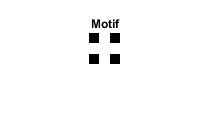

% extraction
Motif=ICroix(120-15:120+15,120-15:120+15);
% affichage du motif ac imshow()
figure;
imshow(Motif);
title('Motif')

Calcul de la corrélation croisée , 

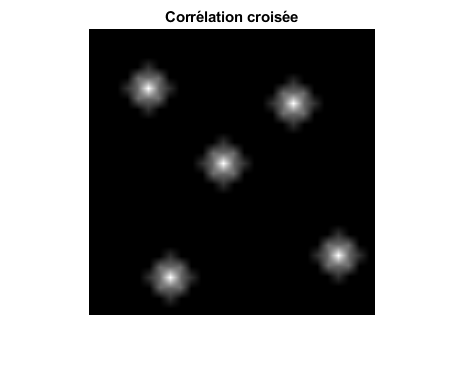

% Calcul de la corrélation croisée de ICroix et Motif à l'aide de xcorr(2),
Corr=xcorr2(ICroix,Motif);
% Normalisation de la corrélation
Corr=Corr/max(Corr(:));
% Affichage des résultats 
imshow(Corr)
title('Corrélation croisée')

Reacadrer l'image de corrélation sur les 256 pixels centraux puis, à l'aide de la fonction find() relever la position des maximums de la matrice Corr

%prise des 256 pixels centraux
Corr=Corr(16:end-16,16:end-16);
% utiliation de find() pour stocker les positions des maximums
[li,col]=find(Corr==1);


Ajouter un marker à l'aide de insertMarker() sur les positions trouvées puis afficher les prédiction sur l'image ICroix

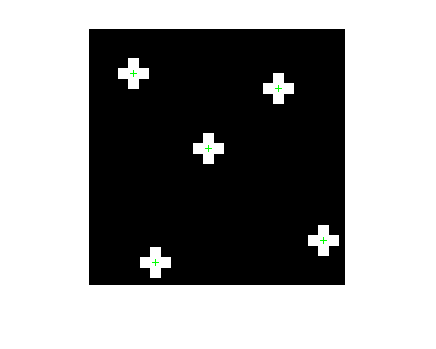

pos=zeros(5,2);
for k=1:5
    pos(k,1)=col(k);
    pos(k,2)=li(k);
end
im_new=insertMarker(ICroix,pos);
% ou plus simplement: im_new=insertMarker(ICroix,[col li]);
%im_new=insertMarker(ICroix,[col li]);
figure;
imshow(im_new)

Vérifier que les marqueurs sont bien possitionnés au centre des motifs de croix.